**Taller evaluativo 3**

Dana Coronel Jimenez

**Ecuaciones diferenciales**

Profesora Olga Lucia Montoya

Octubre 1, 2023

**Introducción**

En este taller se resolverá numéricamente, por el método de Runge-Kutta haciendo uso de la función ode45, la ecuación de estado de un modelo epidemiológico SIRV (SIR con vacunados) no lineal.

**Descripción del modelo**

Dada la siguiente la siguiente ecuación de estado de cuarto orden no lineal de un modelo SIRV (susceptibles-infectados-recuperados-vacunados) para cierta enfermedad contagiosa entre humanos, resolverla utilizando elmétodo numérico de Runge-Kutta implementado en la función ode45 de MATLAB. 

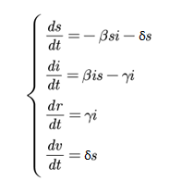

Caso para estudiar (hay epidemia, R0 > 1):

β = 0.1 // **tasa de transmisión.**

γ = 0.02 // ** tasa de recuperación y aislamiento.**

δ = 0.001 //** tasa de vacunación.**

**s**(0) = 0.8 // **porcentaje de personas susceptibles (pueden contraer la enfermedad).**

**i**(0) = 0.1// **porcentaje de personas infectadas.**

**r**(0) = 0 // **porcentaje de personas recuperadas(y que no vuelven a contraer la enfermedad, es**

**decir, quedan inmunes).**

personas infectadas

**v**(0) = 0.1// **porcentaje de personas vacunadas.**

Eje (Y) S,I,R,V, (X) el tiempo

**Punto 1**

Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)

**a) **Resolver y graficar S,I,R,V como función del tiempo en una sola figura.

%Definición de variables de manera simbólica
syms s(t) i(t) r(t) v(t)

%Definición de variables beta, gamma y delta.
beta = 0.1; gamma = 0.02; delta= 0.001; 

%Definicipon de a ecuación de la función inicial (f1). Representando la derivada con respecto al tiempo del porcentaje de personas susceptibles.
f1 = -beta*s*i - delta*s; 

%Definición de la ecuación f2, donde la derivada con respecto al tiempo representa el porcentaje de personas infectadas.
f2 = beta*s*i - gamma *i  

$$f2(t) = \frac{i\left(t\right)\,s\left(t\right)}{10}-\frac{i\left(t\right)}{50}$$

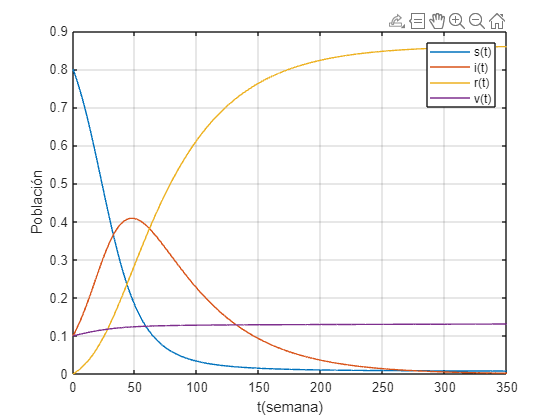

%Definición de la ecuación f3, en ella se muestra la derivada con respecto al tiempo del porcentaje de personas recuperadas.
f3= gamma*i; 

%Definición de la ecuación f4, representando la derivada con respecto al tiempo del porcentaje de personas vacunadas.
f4= delta*s; 

%parte derecha de la ecuación de estado.
f=odeFunction([f1 f2 f3 f4],[s i r v]); 

%Tamaño del paso.
h = 0.1;

%Tiempo minimo.
tmin = 0;

%Tiempo máximo
tmax = 350;

%Intervalo de tiempo
tspan = tmin:h:tmax; 

%Condiciones iniciales
ci = [0.8 0.1 0 0.1]; [t1,x1] = ode45(f,tspan,ci); 

%Graficando
plot(t1,x1), xlabel('t(semana)'); ylabel('Población'), grid,legend({'s(t)', 'i(t)', 'r(t)', 'v(t)'})

**Análisis:**

En esta gráfica se logra ver que, aproximadamente, en la semana 50 es cuando hay más infectados. El pico de la pandemia se dió cuando un 40% de población estuvo infectada. Asi mismo se logra ver que cuando decrece la cifra de infectados, el porcentaje de personas recuperadas aumenta. Adicionalmente cuando el porcentaje de la población infectada se acerca a cero, la curva de personas recuperadas se empieza a aplanar.

Por otro lado, después del pico de la pandemia, cuando empieza a decrecer la población infectada, el porcentaje de personas susceptibles decrece y la curva se empieza a aplanar

**        b) **Aumentar V=(0) hasta que llegue a 0.15

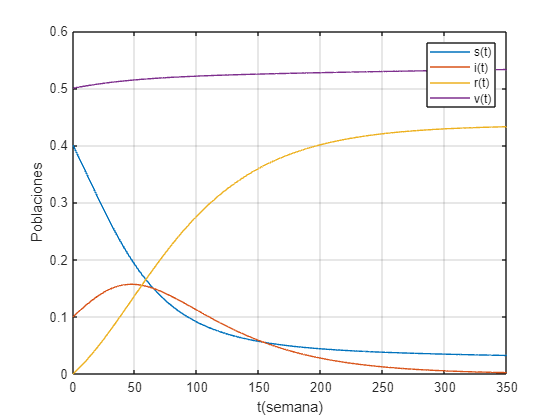

%Cambio de valores (s,v).
ci = [0.4 0.1 0 0.5]; [t1,x1] = ode45(f,tspan,ci);

%Grafica.
plot(t1,x1), 

%Nombre de los ejes.
xlabel('t(semana)'),
ylabel('Poblaciones'), 

%Cuadricula.
grid, 

%Nombre de cada función graficada.
legend({'s(t)','i(t)','r(t)','v(t)'})

**Análisis:**

Se observó que, al aumentar el porcentaje de personas vacunadas, hubo una reducción significativa del porcentaje de personas infectadas y susceptibles a la enfermedad. Además, se observó una disminución en el pico de la pandemia con , aproximadamente, un 15% de la población infectada, en comparación a la gráfica pasada que se dió cuando un 40% de la población estaba infectada. Se dió un aplanamiento de la curva de las personas susceptibles y recuperadas. Estos resultados sugieren que la vacunación es una estrategia efectiva para controlar la propagación de una enfermedad infecciosa. 

A partir de las gráficas podemos determinar que el porcentaje mínimo de vacunados para que los infectados aumenten solo en un 50% es de: v=0.52.

**Punto 2**

Graficar sólo la solución i(t) con un aumento sólo de i(0) y usando al menos 5 valores. Observar que al cambiar i(0) cambia s(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.

**Valores**

I(0)= 0.1, 0.2, 0.3, 0.4, 0.5

s(0)= 0.8, 0.7, 0.6, 0.5, 0.4

**a)** Graficar la función I(t) y aumentar la condición inicial I(0) al menos 5 valores.

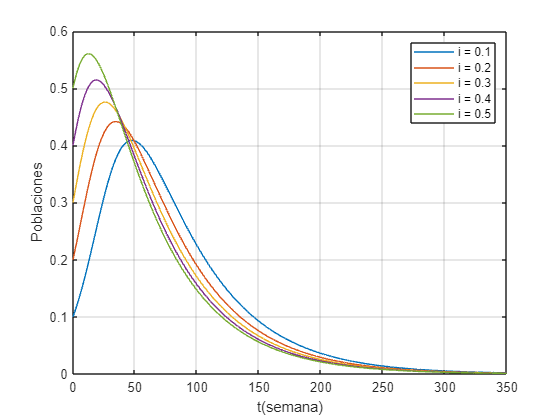

% Definición de variables.
syms i(t)
% Definición de beta, gamma y delta con sus respectivos valores.
beta = 0.1; 
gamma = 0.02; 
delta = 0.001;

%Ecuaciones del modelo SIRV.
F1 = -beta*s*i - delta*s;
F2 = beta*s*i - gamma*i;
F3 = gamma*i;
F4 = delta*s;

%parte derecha de la ecuación de estado.
f=odeFunction([F1 F2 F3 F4],[s i r v]);

%Tamaño del paso.
h = 0.1;

%Tiempo mínimo.
tmin = 0;

%Tiempo máximo.
tmax = 350; 

%Metodo númerico.
tspan = tmin:h:tmax;

%Valores iniciales subiendo I = 0.1 x 5 repeticiones.
ci = [0.8 0.1 0 0.1]; [t1,x1] = ode45(f,tspan,ci);
ci = [0.7 0.2 0 0.1]; [t2,x2] = ode45(f,tspan,ci);
ci = [0.6 0.3 0 0.1]; [t3,x3] = ode45(f,tspan,ci);
ci = [0.5 0.4 0 0.1]; [t4,x4] = ode45(f,tspan,ci);
ci = [0.4 0.5 0 0.1]; [t5,x5] = ode45(f,tspan,ci);

%Grafica de los valores en I, (unicamente la segunda columna).
plot(t1,x1(:,2), t2,x2(:,2), t3,x3(:,2), t4,x4(:,2), t5,x5(:,2))

%Nombre de los ejes.
xlabel('t(semana)'),
ylabel('Poblaciones'), 

%Añadir cuadrícula a la gráfica.
grid, 

%Nombre de cada función graficada.
legend({'i = 0.1','i = 0.2','i = 0.3','i = 0.4','i = 0.5'})

**Análisis:**

la variación del parámetro i(t) afecta la propagación de una enfermedad infecciosa y cómo se puede evidenciar en las curvas de las personas infectadas a lo largo del tiempo. Cuando el valor de i(t) aumenta, la curva de la enfermedad se desplaza hacia la izquierda, lo que indica que el pico de la pandemia aparece más rápido. Además, cuando el porcentaje de población infectada comienza a disminuir, las curvas que tienen un valor de i(t) más alto disminuyen el porcentaje de personas infectadas más rápido que la curva original que tiene un valor de i(t) de 0.1.

También se observa que el pico de la pandemia varía dependiendo del valor de i(t), lo que indica que a medida que se aumenta este valor, más población es afectada por la enfermedad. Estos resultados nos dicen que el valor de i(t) es un parámetro que se debe considerar en los modelos matemáticos de la propagación de enfermedades infecciosas y su variación puede tener un impacto significativo en la evolución de la enfermedad en cuestión.

**Punto 3**

Graficar sólo la solución i(t) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. 

¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.

**a) **Graficar I(t) aumentando B= 0.05, 0.15, 0.2, 0.25, 0.3.

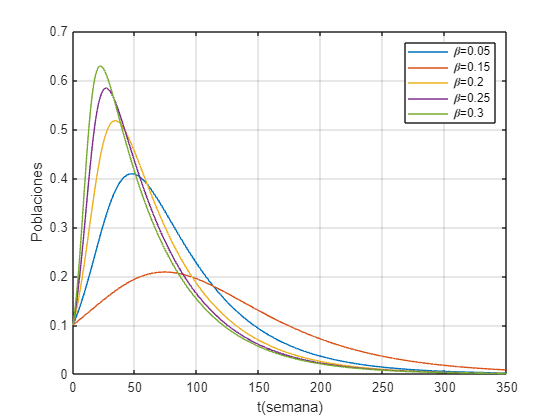

% Definición de variables.
syms s(t)
% Definición de beta, gamma y delta y sus respectivos valores.
beta = 0.1; 
gamma = 0.02; 
delta = 0.001;

%Ecuaciones del modelo SIRV.
F1 = -beta*s*i - delta*s;
F2 = beta*s*i - gamma*i;
F3 = gamma*i;
F4 = delta*s;

%parte derecha de la ecuación de estado.
f=odeFunction([F1 F2 F3 F4],[s i r v]);

%Tamaño del paso.
h = 0.1;

%Tiempo mínimo.
tmin = 0;

%Tiempo máximo.
tmax = 350; 

%Método númerico.
tspan = tmin:h:tmax;

%Valores iniciales.
ci = [0.8 0.1 0 0.1]; 

%Aumentando los valores de beta
beta = 0.05;
F1 = -beta*s*i - delta*s;
F2 = beta*s*i - gamma*i;
f = odeFunction([F1 F2 F3 F4],[s i r v]);
[t2,x2] = ode45(f,tspan,ci);%Utilizando  Runge-Kutta en la función ode45


beta = 0.15;
F1 = -beta*s*i - delta*s;
F2 = beta*s*i - gamma*i;
f = odeFunction([F1 F2 F3 F4],[s i r v]);
[t3,x3] = ode45(f,tspan,ci);%Utilizando  Runge-Kutta en la función ode45



beta = 0.2;
F1 = -beta*s*i - delta*s;
F2 = beta*s*i - gamma*i;
f = odeFunction([F1 F2 F3 F4],[s i r v]);
[t4,x4] = ode45(f,tspan,ci);%Utilizando  Runge-Kutta en la función ode45



beta = 0.25;
F1 = -beta*s*i - delta*s;
F2 = beta*s*i - gamma*i;
f = odeFunction([F1 F2 F3 F4],[s i r v]);
[t5, x5] = ode45(f,tspan,ci);%Utilizando  Runge-Kutta en la función ode45



beta = 0.3;
F1 = -beta*s*i - delta*s;
F2 = beta*s*i - gamma*i;
f = odeFunction([F1 F2 F3 F4],[s i r v]);
[~,~] = ode45(f,tspan,ci);%Utilizando  Runge-Kutta en la función ode45



%Gráfica.
plot(t1,x1(:,2), t2,x2(:,2), t3,x3(:,2), t4,x4(:,2), t5,x5(:,2)), 

%Nombre de los ejes.
xlabel('t(semana)'),
ylabel('Poblaciones'), 

%Cuadrícula.
grid, 

%Nombre de cada función graficada.
legend({'\beta=0.05','\beta=0.15','\beta=0.2','\beta=0.25','\beta=0.3'})

**Análisis:**

En la gráfica podemos evidenciar que en cuanto a la tasa representada por B (beta) sea más alta los picos de la pandemia aparecerán serán proporcionales, aumnetando también con rapidez y por consecuencia, despues del pico, el porcentaje de personas afectadas disminuye mucho mas rápido. En el caso en que B (beta) tiene un valor a cero, de nuevo es porporcional representando los valores más bajos en la curva, logrando acercarse al 0% de personas contagiadas mucho más rápido que las otras curvas. 

**Punto 4**

Graficar sólo la solución i(t) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser

manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema.

¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.

**a) **Graficar I(t), aumentando R= 0.02, 0.03, 0.04, 0.05

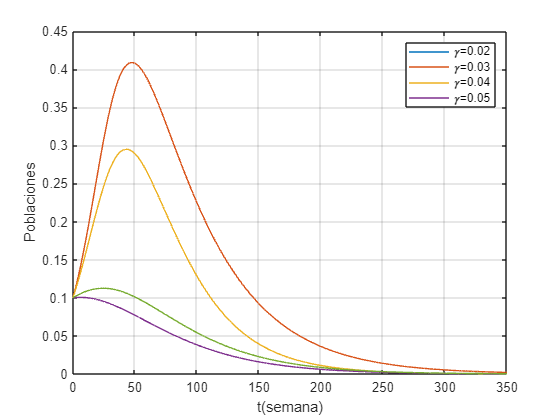

% Definición de variables.
syms i(t)

% Definición de beta, gamma y delta con sus respectivos valores.
beta = 0.1; 
gamma = 0.02; 
delta = 0.001;

%Ecuaciones del modelo SIRV.
F1 = -beta*s*i - delta*s;
F2 = beta*s*i - gamma*i;
F3 = gamma*i;
F4 = delta*s;

f=odeFunction([F1 F2 F3 F4],[s i r v]);

%Tamaño del paso.
h = 0.1;

%Tiempo mínimo.
tmin = 0;

%Tiempo máximo.
tmax = 350; 

%Método númerico.
tspan = tmin:h:tmax;

%Valores iniciales.
ci = [0.8 0.1 0 0.1]; 

%aumentando los valores de gamma
gamma = 0.02;
F2 = beta*s*i - gamma*i;
F3 = gamma*i;
f = odeFunction([F1 F2 F3 F4],[s i r v]);
[t2,x2] = ode45(f,tspan,ci); %Utilizando  Runge-Kutta en la función ode45



gamma = 0.03;
F2 = beta*s*i - gamma*i;
F3 = gamma*i;
f = odeFunction([F1 F2 F3 F4],[s i r v]);
[t3,x3] = ode45(f,tspan,ci); %Utilizando  Runge-Kutta en la función ode45



beta = 0.04;
F2 = beta*s*i - gamma*i;
F3 = gamma*i;
f = odeFunction([F1 F2 F3 F4],[s i r v]);
[t4,x4] = ode45(f,tspan,ci); %Utilizando  Runge-Kutta en la función ode45



beta = 0.05;
F2 = beta*s*i - gamma*i;
F3 = gamma*i;
f = odeFunction([F1 F2 F3 F4],[s i r v]);
[t5,x5] = ode45(f,tspan,ci); %Utilizando  Runge-Kutta en la función ode45



%Grafica.
plot(t1,x1(:,2), t2,x2(:,2), t3,x3(:,2), t4,x4(:,2), t5,x5(:,2)), 

%Nombre de los ejes.
xlabel('t(semana)'),
ylabel('Poblaciones'), 

%Cuadricula.
grid, 

%Nombre de cada función graficada.
legend({'\gamma=0.02','\gamma=0.03','\gamma=0.04','\gamma=0.05'})

**Análisis:**

Cuando el valor de gamma (γ) aumenta, se produce una disminución en la curva de infectados, ya que más personas se recuperan y se aíslan más enfermos, lo que contribuye a reducir la propagación de la enfermedad en la población. Por otro lado, se indica que el valor mínimo de γ encontrado para evitar una epidemia es de 0,002; lo que significa que si la tasa de recuperación y aislamiento es mayor a este valor, el número de personas infectadas disminuirá hasta el punto de acabar la epidemia.

**Punto 5**

Graficar sólo la solución i(t) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales

debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se

puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de

manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de

10% (es decir, llegue a 0.2)? Interpretar los resultados.

**a) **Graficar I(t) aumentando δ = 0.001, 0.002, 0.003, 0.004, 0.032

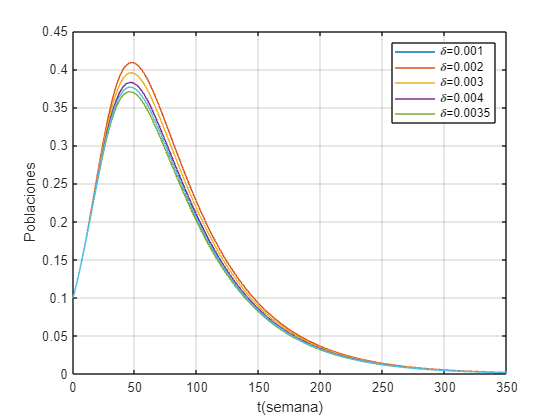

% Definición de variables.
syms i(t)

% Definición de beta, gamma y delta y sus respectivos valores.
beta = 0.1; 
gamma = 0.02; 
delta = 0.001;

%Ecuaciones del modelo SIRV.
F1 = -beta*s*i - delta*s;
F2 = beta*s*i - gamma*i;
F3 = gamma*i;
F4 = delta*s;

%Lado derecho de la ecuación de estado
f=odeFunction([F1 F2 F3 F4],[s i r v]);

%Tamaño del paso.
h = 0.1;

%Tiempo mínimo.
tmin = 0;

%Tiempo máximo.
tmax = 350; 

%Método númerico.
tspan = tmin:h:tmax;

%Valores iniciales.
ci = [0.8 0.1 0 0.1]; 

%Aumentando los valore de delta
delta = 0.001;
F1 = -beta*s*i - delta*s;
F4 = delta*s;F4 = delta*s;
f=odeFunction([F1 F2 F3 F4],[s i r v]);
[t2,x2] = ode45(f,tspan,ci); %Utilizando  Runge-Kutta en la función ode45



delta = 0.002;
F1 = -beta*s*i - delta*s;
F4 = delta*s;F4 = delta*s;
f=odeFunction([F1 F2 F3 F4],[s i r v]);
[t3,x3] = ode45(f,tspan,ci); %Utilizando  Runge-Kutta en la función ode45



delta = 0.003;
F1 = -beta*s*i - delta*s;
F4 = delta*s;F4 = delta*s;
f=odeFunction([F1 F2 F3 F4],[s i r v]);
[t4,x4] = ode45(f,tspan,ci); %Utilizando  Runge-Kutta en la función ode45



delta = 0.004;
F1 = -beta*s*i - delta*s;
F4 = delta*s;F4 = delta*s;
f=odeFunction([F1 F2 F3 F4],[s i r v]);
[t5,x5] = ode45(f,tspan,ci); %Utilizando  Runge-Kutta en la función ode45



delta = 0.0035;
F1 = -beta*s*i - delta*s;
F4 = delta*s;F4 = delta*s;
f=odeFunction([F1 F2 F3 F4],[s i r v]);
[t6,x6] = ode45(f,tspan,ci); %Utilizando  Runge-Kutta en la función ode45


%Gráfica.
plot(t1,x1(:,2), t2,x2(:,2), t3,x3(:,2), t4,x4(:,2), t5,x5(:,2),t6,x6(:,2)), 

%Nombre de los ejes.
xlabel('t(semana)'),
ylabel('Poblaciones'), 

%Añadiéndole cuadrícula a la gráfica.
grid, 

%Nombre de cada función graficada.
legend({'\delta=0.001','\delta=0.002','\delta=0.003','\delta=0.004','\delta=0.0035'})

**Análisis:**

Cuando se aumenta la tasa de vacunación, se observa en las gráficas que el número de infectados disminuye, ya que, con la vacunación se logra que más personas sean inmunes al virus, y esto ayuda a reducir la epidemia. Se indica también que se ha encontrado un valor mínimo de δ necesario para que los infectados lleguen a 0.2, y este valor es de = 0.032.

**Conclusiones:**

El método de Runge-Kutta es una herramienta eficiente en MatLab para obtener una solución precisa y rápida de un problema específico como el que se desarrolla en este taller, donde la vacunación y el aislamiento son factores clave para reducir y, en algunos casos, eliminar una epidemia en un corto período de tiempo.

Es por esto que, herramientas como la representación visual de los datos mediante gráficas es útil para identificar cambios en las variables y tomar decisiones más informadas sobre la gestión de una epidemia. Demostrando la importancia de las matemáticas y la visualización de datos para abordar y solucionar problemas complejos como una epidemia, y cómo la combinación de medidas como la vacunación y el aislamiento pueden ser efectivas para reducir y prevenir la propagación de una enfermedad infecciosa.